# Video Pre-Processing Algorithm Analysis: Drop Segmentation

**Summary**: Test background subtraction + binarisation (thresholding) method + morphological operations on a series of videos.

- Abs background subtraction method gave the most consistent quality. 

- Otsu method is used to determine treshold value. 

- Developed custom function for drop segmentation (func. file: *segDrop.m*) - combining a series of image manipulation and morphological operation steps.

- Drop segmentation is not perfect - some drops may be incorrectly removed/ fused with other drops in the process.

- Failure mode: 

- i) high drop generation rate so drops are very close together in channel; common in TRI and C12Tab videos. In this case, drops may appear to 'fuse' together. Also, this may lead to presence of artefact in background image, in turn affecting quality of drop segmentation. 

- ii) varying or poor brightness/ contrast across frame; particularly prominent around the frame borders. The selected (global) threshold value may not be as suitable for drops in certain regions.   

Written by: SWC, 17-Feb-2021.

Analysis completed: SWC, 18-Feb-2021.

Processed video: DYE001_S.O.5 cSt 17 e  13 DYE -10kfps x4mag_sh50_C001H001S0008.avi
Using modified algorithm...
Elapsed time is 10.814862 seconds.


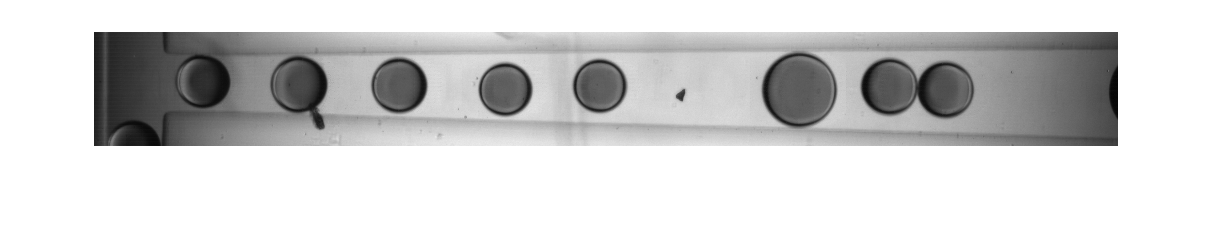

----- Absolute difference -----


Elapsed time is 0.409889 seconds.


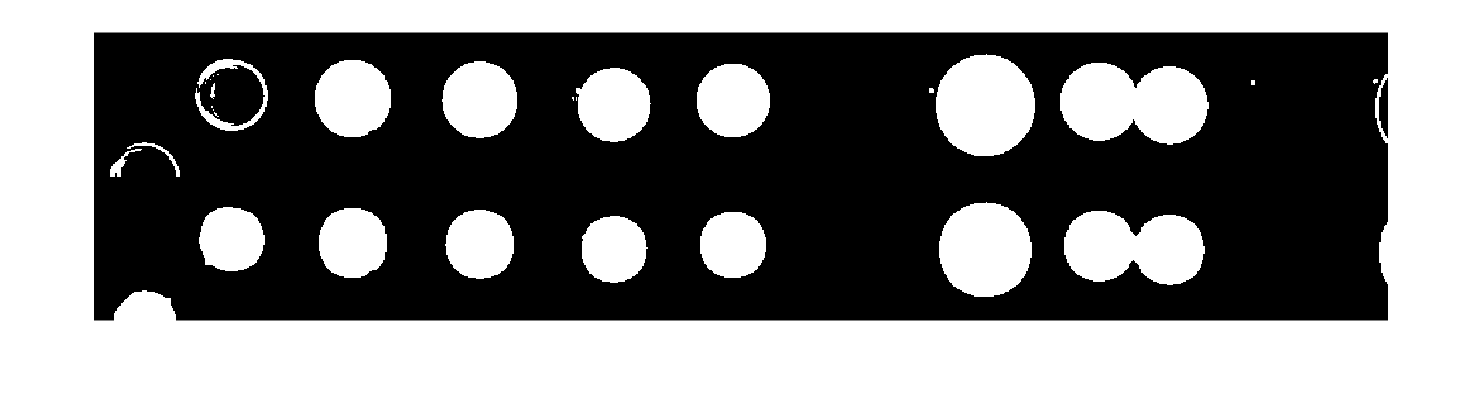

-------------------------------------------


Processed video: DYE002_S.O.5 cSt 13 e  7 DYE -10kfps x4mag_sh50_C001H001S0012.avi
Using modified algorithm...
Elapsed time is 9.675332 seconds.


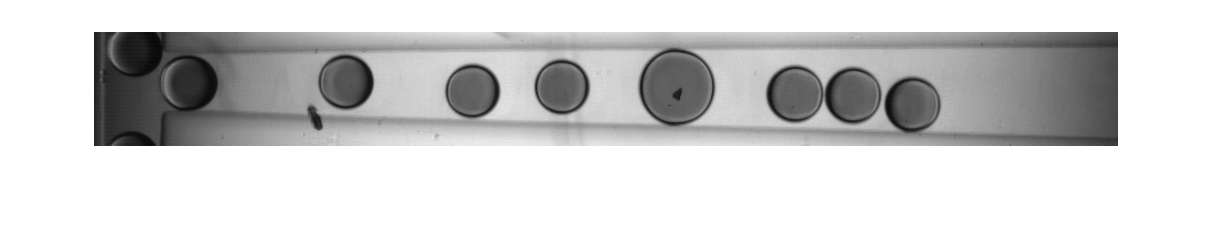

----- Absolute difference -----


Elapsed time is 0.121450 seconds.


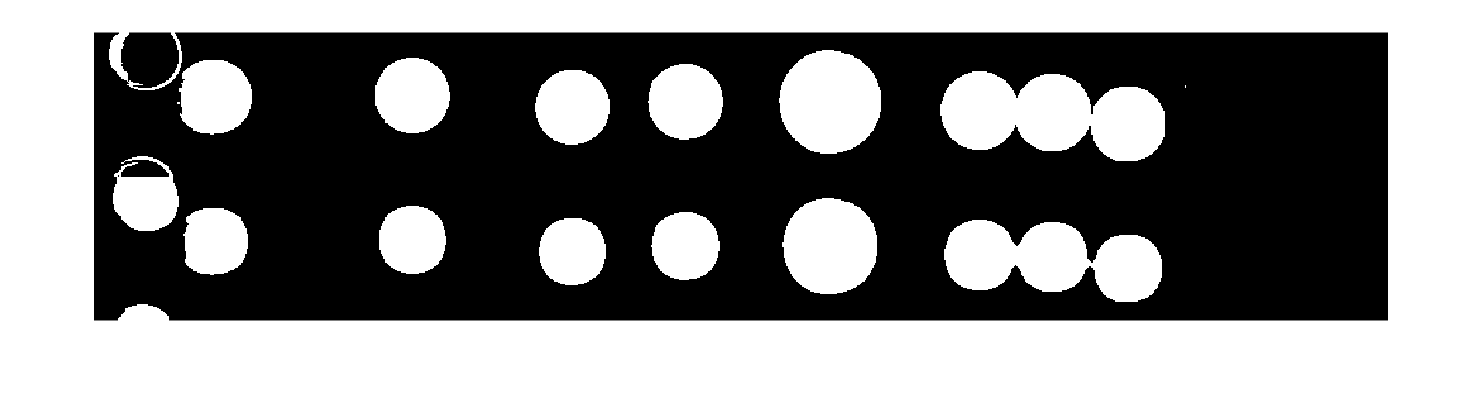

-------------------------------------------


clear
close all

vid_files = dir('DYE*.avi'); % <----- User-defined input 

%% --------- background generation -------------------
for i = 1:numel(vid_files)
    vid_name = vid_files(i).name; % get video file name
    vid = VideoReader(vid_name);
    n = 40; % number of frames used to generate background image
     
    bg = bgGenCmplx(vid_name, n, 'original'); % use complex bg generation method.
    % --- bgGenCmplx method ---
    % 'original': Good with WAT. Varying results with TRI, SDS. Unsuitable
    % for C12Tab.
    % 'modified': Good with WAT, DYE. Suitable for C12Tab (but not
    % perfect). Varying results with TRI, SDS. 
        
%     figure; imshow(bg);
    
%% ----------- load a random video frame for testing -------
    Im = read(vid,randperm(vid.NumFrames,1));
    
    figure; imshow(Im);
    
%% ----------- drop segmentation -------------
    disp('----- Absolute difference -----')
    absIm = rescale(abs(double(Im) - double(bg))); %Note2self:this is same as using mat2gray function
    
    abs_bin1 = imfill(imbinarize(absIm),'holes'); % basic binarisation
    abs_bin2 = imfill(imbinarize(imadjust(stdfilt(absIm)), 0.75*graythresh(absIm)),'holes'); % image filtered and saturated; adjusted threshold
    abs_bin3 = imfill(edge(absIm),'holes'); % sobel edge detection
    abs_bin4 = imfill(edge(absIm,'Canny'),'holes'); % canny edge detection
    abs_bin5 = segDrop(absIm);
    figure; montage({abs_bin1 abs_bin2 abs_bin3 abs_bin4 abs_bin5},'Size', [5 1]);
    
%     disp('----- Standard difference -----')
    stdIm = rescale(double(Im) - double(bg));
%     not displaying results of this, as basically just inverted of
%     'inverted difference', but in practice would like white drops agaisnt
%     dark background, so have used the latter
    
    disp('----- Inverted difference -----')
    invIm = 1 - stdIm;
    inv_bin1 = imfill(imbinarize(invIm),'holes');
    inv_bin2 = imfill(imbinarize(invIm, 0.75*graythresh(invIm)),'holes');
    inv_bin3 = imfill(edge(invIm),'holes'); 
    inv_bin4 = imfill(edge(invIm,'Canny'),'holes');
    inv_bin5 = segDrop(invIm);
    figure; montage({inv_bin1 inv_bin2 inv_bin3 inv_bin4 inv_bin5},'Size', [5 1]);
    
    
%     figure; montage({abs_bin2 abs_bin5}, 'Size', [2 1]);

    disp('-------------------------------------------')
    
end


%% Some other morphological operations trialled. 
% fill2 = imerode(imclose(fill2,strel('diamond',3)), strel('diamond',2)); 
%  ----------------------
% fill2 = imclose(fill2,strel('diamond',3));
% fill2 = imfill(fill2,'holes');
% fill2 = imopen(imerode(fill2,strel('diamond',3)), strel('diamond',1));
% -----------------------
% fill2 = imerode(fill2, strel('diamond',4));


%% Another binarisation method trialled --> did not really work that well?
% test = invIm;
% figure; imshow(test)
% adtest = imadjust(test);
% figure; imshow(adtest)
% that = imtophat(test,strel('disk',20));
% bhat = imbothat(test,strel('disk',20));
% test2 = adtest+that-bhat;
% test2(test2<0) = 0;
% test2(test2>1) = 1;
% figure; imshow(test2)
% fin = imfill(imbinarize(test, 0.7*graythresh(test)),'holes');
% figure; imshow(fin)

% ------------------
% figure; imshow(Im)
% Aa = imfilter(Im,fspecial('disk',10));
% Ab = imfilter(Im,fspecial('disk',5));
% thresh = graythresh(Aa-Ab);
% Ac = (Aa-Ab)>(thresh.*0.4);
% Ad = imfill(Ac,'holes');
% Ae = imerode(Ad,strel('diamond',5));
% figure; imshow(Ae)
